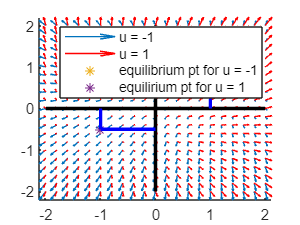

global u;
u = -1;
[X,Y] = meshgrid(-2:0.2:2,-2:0.2:2);
U = X + u;
V = (2*Y) + u;

xL = [-2,2];
yL = [-2,2];


U2 = X + (-u);
V2 = (2*Y) + (-u);

figure
hold on
quiver(X,Y,U,V)
quiver(X,Y,U2,V2,'r')
plot(1,0.5,'*')
plot(-1,-0.5,'*')
line([0 0], yL,'Color','black','LineWidth',2);  %x-axis
line(xL, [0 0],'Color','black','LineWidth',2);  %y-axis
line([-1 -1],[0 -0.5],'Color','blue','LineWidth',2);
line([-1 0],[-0.5 -0.5],'Color','blue','LineWidth',2);
line([0 1],[0.5 0.5],'Color','blue','LineWidth',2);
line([1 1],[0 0.5],'Color','blue','LineWidth',2);
legend('u = -1','u = 1','equilibrium pt for u = -1','equilirium pt for u = 1','','','','','','');
hold off


tstart = 0;
tend = 5;
dt = 0.005;
n = 100;

tspan = transpose(linspace(tstart,tend,n));
% X_final = zeros(1,2);
% tspan2 = zeros(1,1);

xinit = [0.01 0.01];

% for ti = tstart:dt:tend-dt
%     tspan = [ti ti+dt];
%     if xinit(1,1)>0 && xinit(1,2)>0
%     u = -1;
%     elseif xinit(1,1)>0 && xinit(1,2)<0
%     u = -u;
%     elseif xinit(1,1)<0 && xinit(1,2)<0
%     u = 1;
%     else 
%     u = -u;
%     end
% 
%     [t,x] = ode45(@(t,x)integratingfunc(t,x), tspan, xinit);
%     xinit = x(size(x,1),:);
%     X_final = [X_final;x(size(x,1),:)];
%     tspan2 = [tspan2;ti+dt];
% end

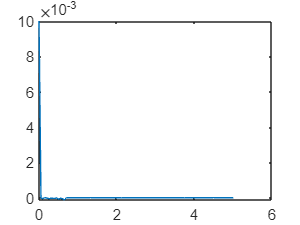


[t,x] = ode45(@(t,x)integratingfunc(t,x), tspan, xinit);
plot(t,x(:,1))

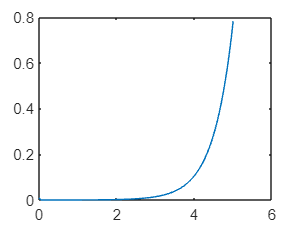

plot(t,x(:,2))

function dxdt = integratingfunc(t,x)
%INTEGRATINGFUNC_SPRINGMASS_SYSTEM Summary of this function goes here
%   Detailed explanation goes here

global u
x1 = x(1);
y = x(2);
u;
if x1>0 && y>0
    u = -1;
elseif x1>0 && y<0
    u = -u;
    %u = 1;
elseif x1<0 && y<0
    u = 1;
else 
    u = -u;
    %u = -1;
end


dxdt = zeros(2,1);
dxdt(1) = x1 + u;
dxdt(2) = (2*y)+u;
end
